# Week 1

data = readtable('Parkinsons.txt');

mean(data.age)

ans = 69.8498

median(data.age)

ans = 68

max(data.age)

ans = 265

min(data.age)

ans = -99

var(data.age)

ans = 322.6917

std(data.age)

ans = 17.9636

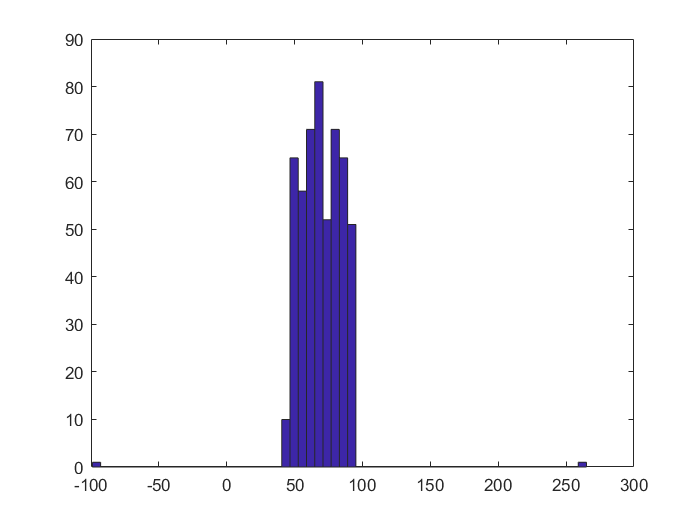

hist(data.age, 60)

This is where I removed the outliers in the data using: 

% data([find(data.age==min(age))],:) = [];

I used code from someone else, but modified it a bit

Jason Joseph Rebello (2020). True Positives, False Positives, True Negatives, False Negatives from 2 Matrices (https://www.mathworks.com/matlabcentral/fileexchange/47364-true-positives-false-positives-true-negatives-false-negatives-from-2-matrices), MATLAB Central File Exchange. Retrieved January 28, 2020.


true_vals = data.actual + data.screen;
true_pos = length(find(true_vals == 2))

true_pos = 252

true_neg = length(find(true_vals == 0))

true_neg = 239


false_vals = data.actual - data.screen;
false_pos = length(find(false_vals == -1))

false_pos = 24

false_neg = length(find(false_vals == 1))

false_neg = 11

length(find(data.screen))/length(data.screen)

ans = 0.5247

ESdata = data(strcmp(data.PStype, 'ES'), :);
PSIdata = data(strcmp(data.PStype, 'PSI'), :);
zscoreESS = zscore(ESdata.PSS);
zscorePSI = zscore(PSIdata.PSS);

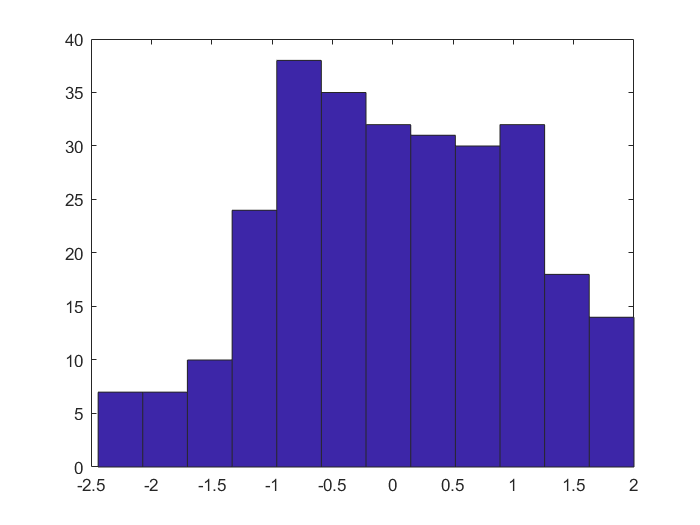

hist(zscoreESS, 12)

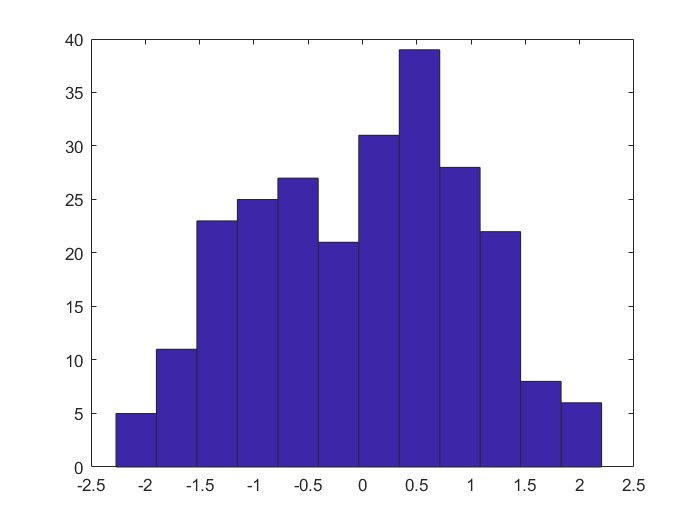

hist(zscorePSI, 12)

true_vals = ESdata.actual + ESdata.screen;
true_pos = length(find(true_vals == 2))

true_pos = 129

true_neg = length(find(true_vals == 0))

true_neg = 135


false_vals = ESdata.actual - ESdata.screen;
false_pos = length(find(false_vals == -1))

false_pos = 11

false_neg = length(find(false_vals == 1))

false_neg = 3